%VARIABLES TO PLAY WITH: T, n, profile
PROFILE = 'polynomial';
T = 10;
n = 1000;

x_init = [0.1, 0.2, 0.35]';
x_fin = [0.3, -0.1, 0.15]';
a = a_plan(PROFILE, T, n, x_init, x_fin);
t = linspace(0, T, n);
x_val = a(1,:);
y_val = a(2,:);
z_val = a(3,:);

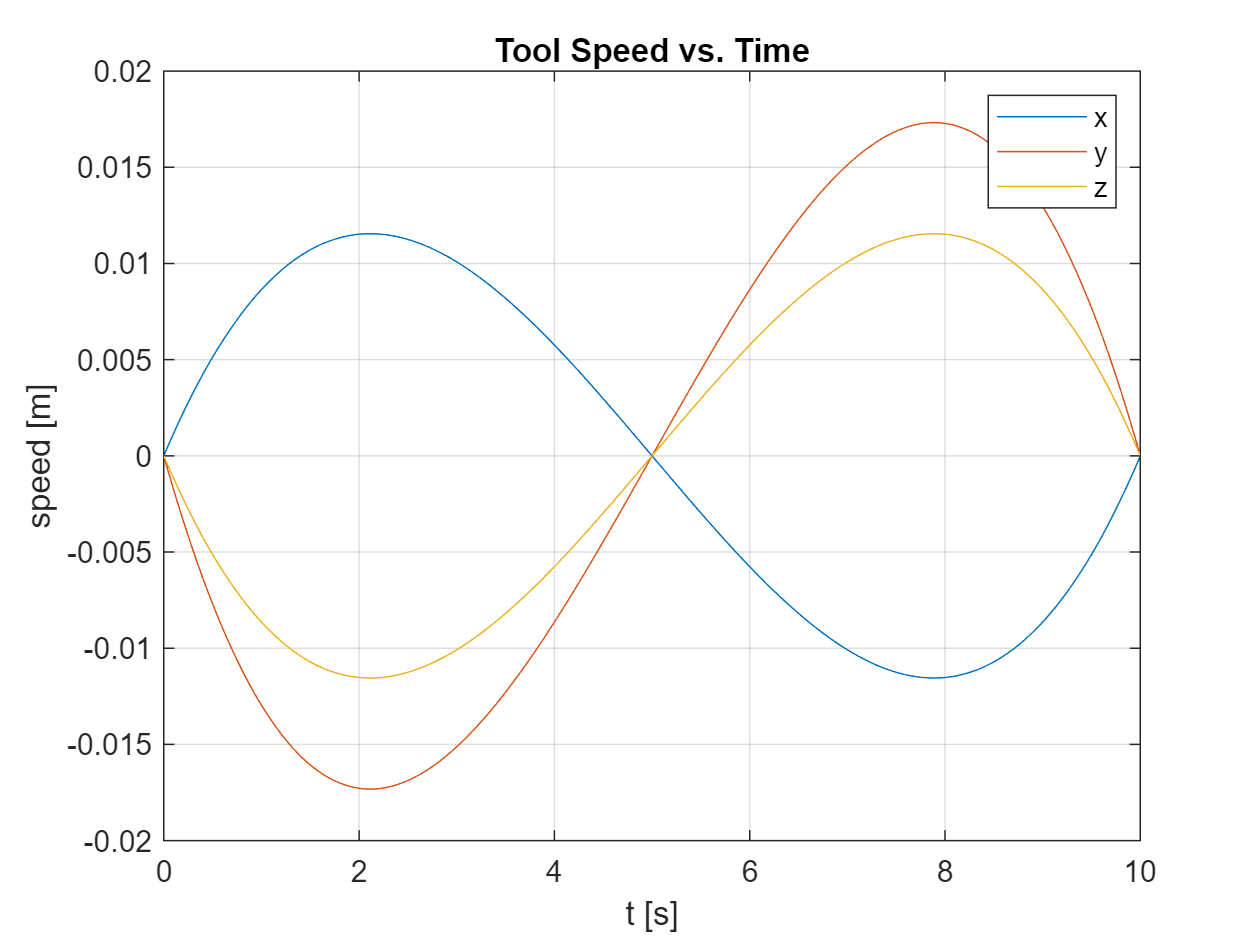

figure(1)
plot(t, x_val)
hold on;
plot(t, y_val)
plot(t, z_val)
hold off
legend('x', 'y', 'z')
grid on;
xlabel('t [s]')
ylabel('speed [m]')
title('Tool Speed vs. Time')